# Irradiance

clear;
close all;
[~, weather, ~, ~] = loadData();

## Distance Plot

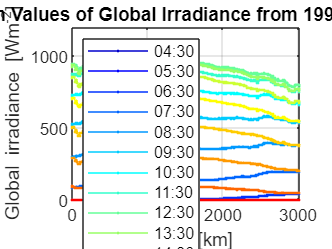

len_time = length(weather.irradiance.timeDur);
colormap_irradiance = jet(len_time);

figure
hold on

for time = 1:len_time
    p = plot(weather.irradiance.dist / 1000, weather.irradiance.irradianceMean(:,time));
    p.LineStyle = '-';
    p.Marker = '.';
    p.Color = colormap_irradiance(time,:);
    p.MarkerSize = 4;

    Time_datetime = datetime(2023, 17, 6, weather.irradiance.time(time,1), weather.irradiance.time(time,2), 0, 'Format','HH:mm');
    p.DisplayName = char(Time_datetime);
end

x_max = weather.irradiance.dist(end) / 1000;
xlim([0 x_max]);
ylim([0 1200]);

xlabel('Space [km]');
ylabel('Global irradiance [Wm^{-2}]'); 
grid on
box on

lg = legend('Location','west');
lg.FontSize = 8;

title_name = "Mean Values of Global Irradiance from 1990 to 2021";
title(title_name)

hold off

## Time Plot

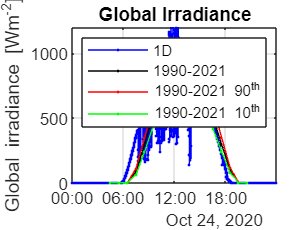

interestDay = datetime(2020, 10, 24);

figure
hold on

p = plot(weather.irradiance1D.time, weather.irradiance1D.Gtotal);
p.LineStyle = '-';
p.Marker = '.';
p.Color = 'b';
p.MarkerSize = 4;
p.DisplayName = '1D';

Time_datetime = datetime(year(interestDay), month(interestDay), day(interestDay), weather.irradiance.time(:,1), weather.irradiance.time(:,2), 0);
p = plot(Time_datetime, weather.irradiance.irradianceMean(1,:));
p.LineStyle = '-';
p.Marker = '.';
p.Color = 'black';
p.MarkerSize = 4;
p.DisplayName = '1990-2021';

p = plot(Time_datetime, weather.irradiance.irradiance90(1,:));
p.LineStyle = '-';
p.Marker = '.';
p.Color = 'red';
p.MarkerSize = 4;
p.DisplayName = '1990-2021 90^{th}';

p = plot(Time_datetime, weather.irradiance.irradiance10(1,:));
p.LineStyle = '-';
p.Marker = '.';
p.Color = 'green';
p.MarkerSize = 4;
p.DisplayName = '1990-2021 10^{th}';

x_min = datetime(year(interestDay), month(interestDay), day(interestDay), 0, 0, 0);
x_max = datetime(year(interestDay), month(interestDay), day(interestDay), 23, 59, 0);
xlim([x_min x_max]);
ylim([0 1200]);

xtickformat('HH:mm');

ylabel('Global irradiance [Wm^{-2}]'); 
grid on
box on

title_name = "Global Irradiance";
title(title_name)

legend()

box on
grid on
hold off